v_air  = out.logsout.get("v_AirspeedSensor").Values.Data;
v_real = out.logsout.get("v").Values.Data;
a_acc  = out.logsout.get("a_Acc").Values.Data;
a_real = out.logsout.get("a_tot").Values.Data;

t = out.logsout.get("v").Values.Time;
dt = mean(diff(t));


% Measurement noise (airspeed sensor)
R = var(v_air - v_real);

% Accelerometer/model error
Q = var(a_acc - a_real) * dt^2;

fprintf('R = %.10f\n',R);

R = 112.5117088953


fprintf('Q = %.10f\n',Q);

Q = 0.0000000931


fprintf('Q/R = %.10f\n',Q/R);

Q/R = 0.0000000008


Q_values = [0.1 1 5 10 25 50 100];

rmse_kal = zeros(size(Q_values));
v_store = zeros(length(v_real), length(Q_values));

for i = 1:length(Q_values)

    Q = Q_values(i);

    v_est = zeros(size(v_real));
    P = 10;
    v_est(1) = v_air(1);

    for k = 2:length(v_real)

        v_pred = v_est(k-1) + a_acc(k)*dt;
        P_pred = P + Q;

        K = P_pred/(P_pred + R);

        v_est(k) = v_pred + K*(v_air(k)-v_pred);
        P = (1-K)*P_pred;

    end

    v_store(:,i) = v_est;
    rmse_kal(i) = sqrt(mean((v_est-v_real).^2));

end
rmse_air = sqrt(mean((v_air-v_real).^2));

disp(table(Q_values', rmse_kal', 'VariableNames', {'Q','Kalman_RMSE'}))

     Q     Kalman_RMSE
    ___    ___________

    0.1      23.688   
      1      23.692   
      5      23.693   
     10      23.693   
     25      23.694   
     50      23.694   
    100      23.694   



fprintf('Airspeed RMSE = %.3f m/s\n', rmse_air);

Airspeed RMSE = 23.694 m/s



[best_rmse, idx] = min(rmse_kal);
best_Q = Q_values(idx);

fprintf('Best Q = %.3f\n', best_Q);

Best Q = 0.100


fprintf('Best Kalman RMSE = %.3f m/s\n', best_rmse);

Best Kalman RMSE = 23.688 m/s


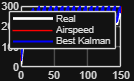

figure
plot(t, v_real, 'w', 'LineWidth', 2)
hold on
plot(t, v_air, 'r')
plot(t, v_store(:,idx), 'b', 'LineWidth', 1.5)
legend('Real','Airspeed','Best Kalman')
grid on